Read data

T = readtable('stock1.xlsx', 'Sheet', 4);

Stock's of Company name

symbol = T.Properties.VariableNames(2:end)'

symbol = 21×1 cell array
    {'AAPL' }
    {'AEP'  }
    {'COST' }
    {'CVX'  }
    {'DUK'  }
    {'ECL'  }
    {'EXR'  }
    {'FDX'  }
    {'GOOGL'}
    {'HAL'  }
    {'HSY'  }
    {'JPM'  }
    {'KDP'  }
    {'LHX'  }
    {'MS'   }
    {'MSFT' }
    {'PLD'  }
    {'SCCO' }
    {'SHW'  }
    {'UNH'  }
    {'V'    }


Calculate the quarter return of original table

quarterlyReturn =T{:,2:end}

quarterlyReturn =     0.0977   -0.0976    0.0437   -0.0231   -0.0685   -0.0793   -0.1795    0.0466    0.1166   -0.0949   -0.1235    0.1416   -0.1577   -0.1610    0.1759    0.0039   -0.1687   -0.2693   -0.1175   -0.1487    0.1233
    0.0708    0.1570    0.0474   -0.0510    0.1463    0.0798    0.1645   -0.0860   -0.1020   -0.1443    0.0552    0.0310    0.1293    0.0715    0.0571   -0.0595    0.1201    0.0711    0.2266    0.1570    0.0445
    0.1938    0.0455    0.1528   -0.0068    0.0510    0.0445    0.0655    0.0708    0.1477   -0.1760   -0.0713    0.0221    0.0707    0.0761    0.0465    0.0518   -0.1292    0.0065   -0.1306    0.0425   -0.0583
   -0.0812    0.0449    0.1132    0.0626         0    0.1438   -0.1061    0.1338    0.0834    0.0882    0.0197    0.1462   -0.0732    0.0209    0.0124    0.1201   -0.0261    0.2131    0.1241   -0.0860    0.0741
    0.0987    0.1254    0.1553   -0.1050    0.1296    0.1610    0.2643   -0.0430    0.0409   -0.0952   -0.0610    0.1610    0.0633    0.19

Build a portfolio with 1% risk rate annually 

p = Portfolio('AssetList',symbol,'RiskFreeRate',0.01/4);
p = estimateAssetMoments(p, quarterlyReturn);
p = setDefaultConstraints(p);

Estimate optimal portfolio (Max Sharpe Ratio)

w1 = estimateMaxSharpeRatio(p)

w1 =     0.0000
    0.0000
    0.6716
    0.0000
    0.0226
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


[risk1, ret1] = estimatePortMoments(p, w1)

risk1 = 0.0754

ret1 = 0.0472

## **The code for Data Visualization is from MATLAB reference**

## **Data Visualization**

Plot the risk and expected return of all asset in the portfolio

f = figure;
tabgp = uitabgroup(f); % Define tab group
tab1 = uitab(tabgp,'Title','Efficient Frontier Plot'); % Create tab
ax = axes('Parent', tab1);
% Extract asset moments from portfolio and store in m and cov
[m, cov] = getAssetMoments(p); 
scatter(ax,sqrt(diag(cov)), m,'oc','filled'); % Plot mean and s.d.
xlabel('Risk')
ylabel('Expected Return')
text(sqrt(diag(cov))+0.0003,m,symbol,'FontSize',7); % Label ticker names

Plot optimal portfolio and efficient frontier using `plotFrontier`

hold on;
[risk2, ret2]  = plotFrontier(p,10);
plot(risk1,ret1,'p','markers',15,'MarkerEdgeColor','k',...
                'MarkerFaceColor','y');
hold off

Visualize table in MATLAB

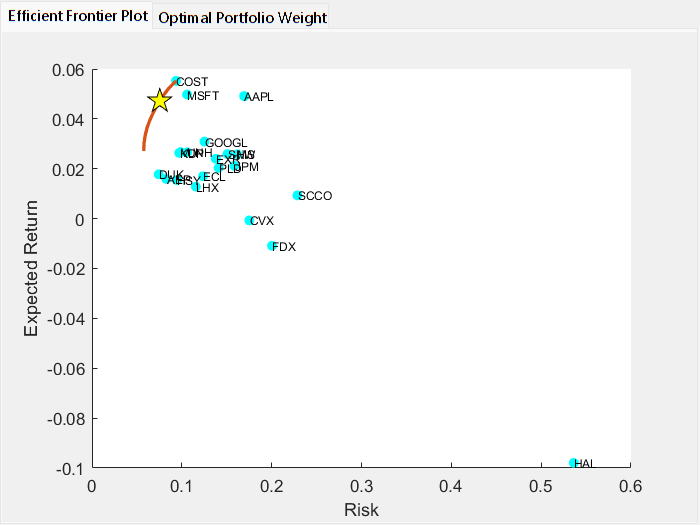

tab2 = uitab(tabgp,'Title','Optimal Portfolio Weight'); % Create tab

% Column names and column format
columnname = {'Ticker','Weight (%)'};
columnformat = {'char','numeric'};

% Define the data as a cell array
% Filter for assets with non-zero weights and ensure column vectors
nonZeroIdx = w1 > 0;
tickers = symbol(nonZeroIdx)';
weights = w1(nonZeroIdx) * 100;

% Force both to be column vectors
tickers = tickers(:);
weights = weights(:);

% Combine into table and convert to cell
data = table2cell(table(tickers, weights));

% Create the uitable
uit = uitable(tab2, 'Data', data,... 
            'ColumnName', columnname,...
            'ColumnFormat', columnformat,...
            'RowName',[]);

% Set width and height
uit.Position(3) = 450; % Widght
uit.Position(4) = 350; % Height